clc; clear; close all;

v = [15.2573 14.8326 14.5700 16.4003 15.7628];
f = 3000:500:5000;
k = 2*pi*f./v; 
h = 0.5974/2 * ones(size(v)) / 1000;

muestras = [1 2 3 4 5];
v = v(muestras);
f = f(muestras);
k = k(muestras);
h = h(muestras);

kh = k.*h;
% Valor inicial para fsolve
eta0 = 0.85;

% Opciones de fsolve
options = optimset('Display','off');

% Usamos arrayfun para aplicar fsolve a cada par (k(i), h(i))
eta_sol = arrayfun(@(khi) ...
    fsolve(@(eta) 4*eta.*tanh(eta*khi)./tanh(khi) - (1+eta.^2).^2, ...
           eta0, options), ...
    kh);

disp('Soluciones para eta:')

Soluciones para eta:


disp(eta_sol)

    0.9237    0.8970    0.8697    0.8698    0.8392



rho = 1050;

x = eta_sol.^2

x =     0.8533    0.8046    0.7564    0.7566    0.7043


y = rho*v.^2

y = 1.0e+05 *

    2.4442    2.3101    2.2290    2.8242    2.6089


% Ajuste lineal (grado 1)
p = polyfit(x, y, 1);

% Pendiente y ordenada al origen
m = p(1);
b = p(2);

disp(['Recta ajustada: y = ' num2str(m) ' * x + ' num2str(b)])

Recta ajustada: y = -146674.8088 * x + 362003.6795


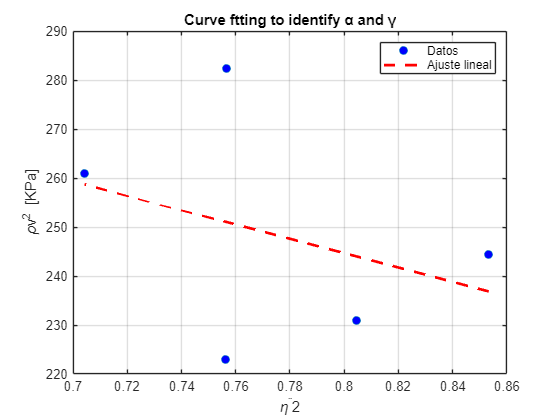


% Calcular valores ajustados
y_fit = polyval(p, x);

% Graficar
figure();
plot(x, y/1000, 'o', 'MarkerFaceColor', 'b'); hold on
plot(x, y_fit/1000, '--r', 'LineWidth', 2);
title('Curve ftting to identify α and γ')
legend('Datos', 'Ajuste lineal')
xlabel('\eta^¨2'); ylabel('\rhov^2 [KPa]');
grid on

% Resultados
alpha = b

alpha = 3.6200e+05

gamma = -m

gamma = 1.4667e+05


stress = alpha - gamma

stress = 2.1533e+05

strain = -1 + (alpha/gamma)^(1/3)

strain = 0.3514

young = stress/strain

young = 6.1276e+05